class1 = 'TURMER';
class2 = 'LUSMEG';

[TURMER_train50x3,TURMER_fs50x3] = retrieveSamples(class1,"train","MaxSamplesPerBird",50,"NumConcatSyllables",3);
[LUSMEG_train50x3,LUSMEG_fs50x3] = retrieveSamples(class2,"train","MaxSamplesPerBird",50,"NumConcatSyllables",3);

[t1,~] = retrieveSamples(class1,"train","MaxSamplesPerBird",40);
[t2,~] = retrieveSamples(class2,"train","MaxSamplesPerBird",40);

## MFCC

bandEdges = linspace(50,22050,42);

[XTrain,YTrain] = createFeatureCells(TURMER_train50x3,LUSMEG_train50x3,class1,class2);
XTrainFs = vertcat(TURMER_fs50x3,LUSMEG_fs50x3);

tooShortIds = cellfun(@(a,b) size(a,1) < round(b*0.03),XTrain,XTrainFs);
XTrain = XTrain(~tooShortIds);
XTrainFs = XTrainFs(~tooShortIds);
YTrain = YTrain(~tooShortIds);

XTrain = cellfun(@(a,b) transpose(mfcc(a,b,"BandEdges",bandEdges)),XTrain,XTrainFs,"UniformOutput",false);

[XTrain,YTrain,XVal,YVal] = createValidationSplit(XTrain,YTrain);

classes = categories(YTrain);
numClasses = numel(classes);

numClasses = 2

numFeatures = size(XTrain{1},1);

filterSize = 3;
numFilters = 32;

layers = [ ...
    sequenceInputLayer(numFeatures)
    convolution1dLayer(filterSize,numFilters,Padding="causal")
    reluLayer
    layerNormalizationLayer
    convolution1dLayer(filterSize,2*numFilters,Padding="causal")
    reluLayer
    layerNormalizationLayer
    globalAveragePooling1dLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

miniBatchSize = 200;

options = trainingOptions("adam", ...
    MiniBatchSize=miniBatchSize, ...
    MaxEpochs=159, ...
    SequencePaddingDirection="left", ...
    ValidationData={XVal,YVal}, ...
    Plots="training-progress", ...
    Verbose=0);

net1 = trainNetwork(XTrain,YTrain,layers,options);

[TURMER_test50x3,TURMER_testFs50x3] = retrieveSamples(class1,"test","NumConcatSyllables",3);
[LUSMEG_test50x3,LUSMEG_testFs50x3] = retrieveSamples(class2,"test","NumConcatSyllables",3);

[XTest,YTest] = createFeatureCells(TURMER_test50x3,LUSMEG_test50x3,class1,class2);
XTestFs = vertcat(TURMER_testFs50x3,LUSMEG_testFs50x3);
tooShortIds = cellfun(@(a,b) size(a,1) < round(b*0.03),XTest,XTestFs);
XTest = XTest(~tooShortIds);
XTestFs = XTestFs(~tooShortIds);
YTest = YTest(~tooShortIds);

XTest = cellfun(@(a,b) transpose(mfcc(a,b,"BandEdges",bandEdges)),XTest,XTestFs,"UniformOutput",false);

YPred = classify(net1,XTest, ...
    MiniBatchSize=miniBatchSize, ...
    SequencePaddingDirection="left");

acc = mean(YPred == YTest)

acc = 0.8129

miniBatchSize = 200;

options = trainingOptions("adam", ...
    MiniBatchSize=miniBatchSize, ...
    MaxEpochs=159, ...
    SequencePaddingDirection="left", ...
    ValidationData={XVal,YVal}, ...
    Plots="training-progress", ...
    Verbose=0);

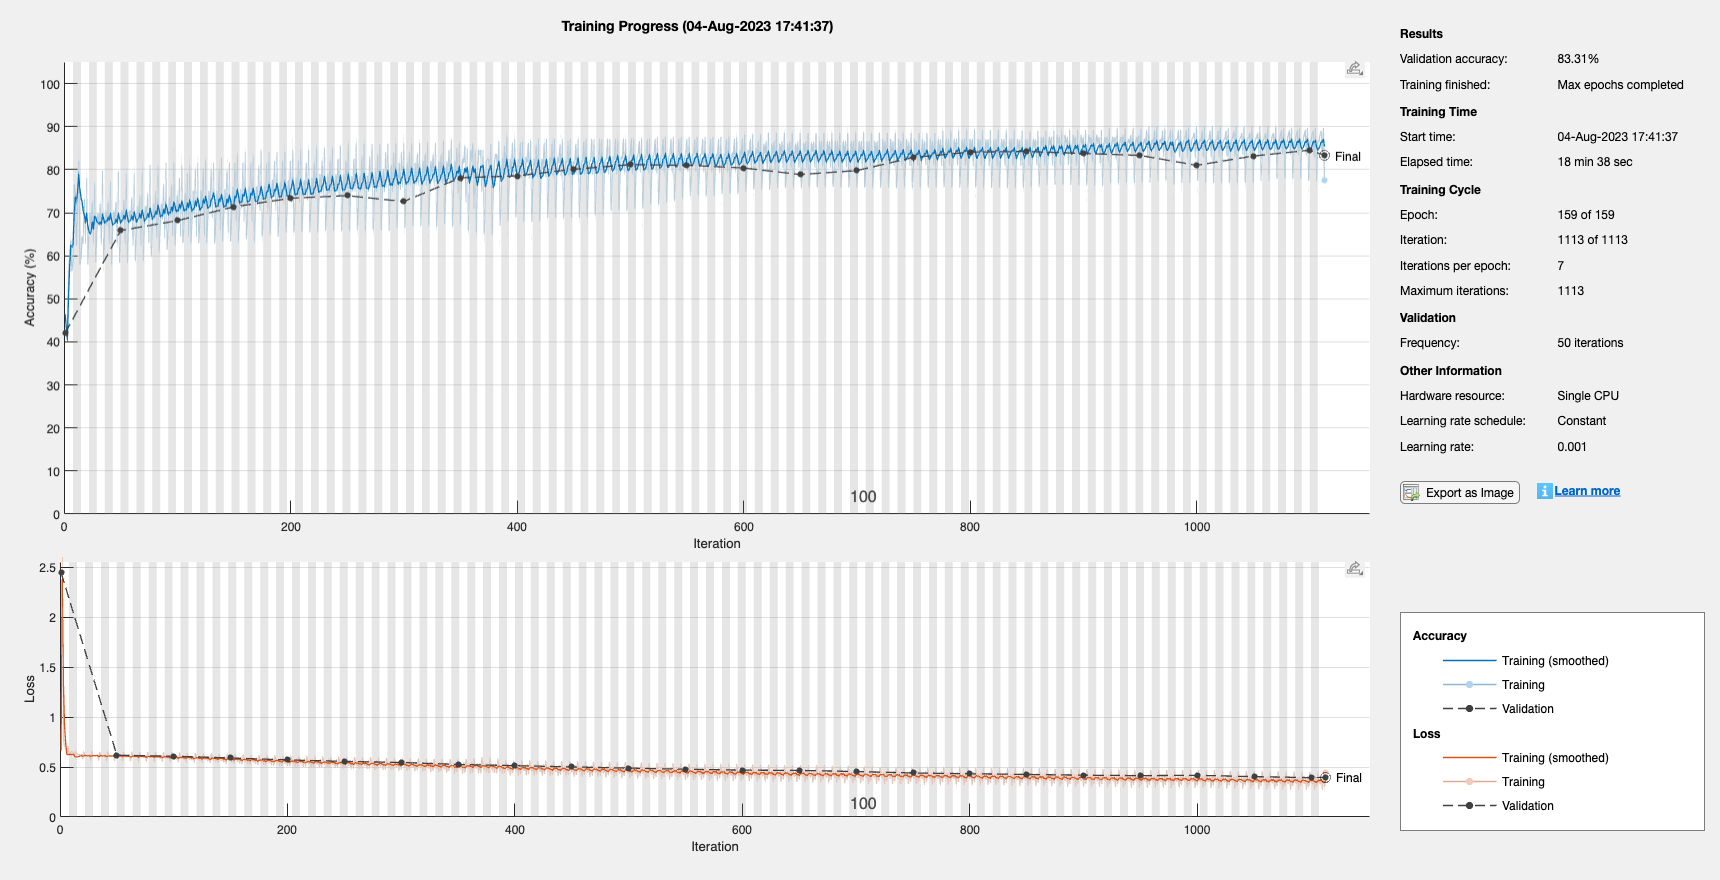

net2 = trainNetwork(XTrain,YTrain,layers,options);

YPred = classify(net2,XTest, ...
    MiniBatchSize=miniBatchSize, ...
    SequencePaddingDirection="left");
acc = mean(YPred == YTest)

acc = 0.8007